clc;
clear all;
close all;
pause('off');
s = tf('s');

# **Applied Linear Controls**

# **Midterm Project**

# **Japnit Sethi**

**Objective:** To design an output feedback control system that can regulate the responses of a multi-input multi-output dynamic system. The Midterm Project will focus on developing and validating an empirical discrete-time state-space model of the dynamic system using system identification methods from the course notes. The Final Project will focus on developing and validating an output feedback controller.  

 For this project, we assume that nothing specific is known about the system dynamics; however, we do know that it has **two outputs** and **one input**, and we know that the system is **open-loop stable**. For this project, you must consider the open-loop plant as a “black box” dynamic system.  This dynamic system has a given **sample rate of 2000 Hz** and already includes appropriate anti-aliasing filters.  You are also given the following: 

**Note**: Open loop stable means that if I excite the system with any kind of signal in an open loop state it will still remain stable

### **Contol Input: **$u_1$

- $\left|u_m \right|\le 10\;V$, Control input signal will saturate or clip at 10 volts

- Control Signal must not saturate the DAC's more than 0.1% of the samples

- You can ignore DAC amplitude quantization

### **Sensor Responses: **$y_1 \;\textrm{and}\;y_2$

- $\left|y_i \right|\le 10\;V$, Sensor signals will saturate or clip at 10 volts

- Sensor signals must not saturate the ADC's for more than 0.1% of the samples

- You can ignore ADC amplitude quantization

- Each sensor signal is corrupted with stationary random noise $n_1 \;\textrm{and}\;n_2$

### ** Dynamic System/Plant:**

Embedded in the s20_plant.p file. y = s20_plant(u); where N is the number of samples, y is a 2xN matrix of sensor responses, u is a 1xN matrix of excitation input. 20 seconds of data in one batch allowed

**Note**: All frequency domain plots must at least range from 1 Hz to the Nyquist frequency.  All frequency limits should be identical and all frequency plots must use a log scale. 

## **Section 1**

Construct an excitation for system identification.  Compute and plot the properly scaled power spectrum for the excitation.  Demonstrate that your excitation signal does not saturate the DAC by plotting your entire excitation in the time domain. 

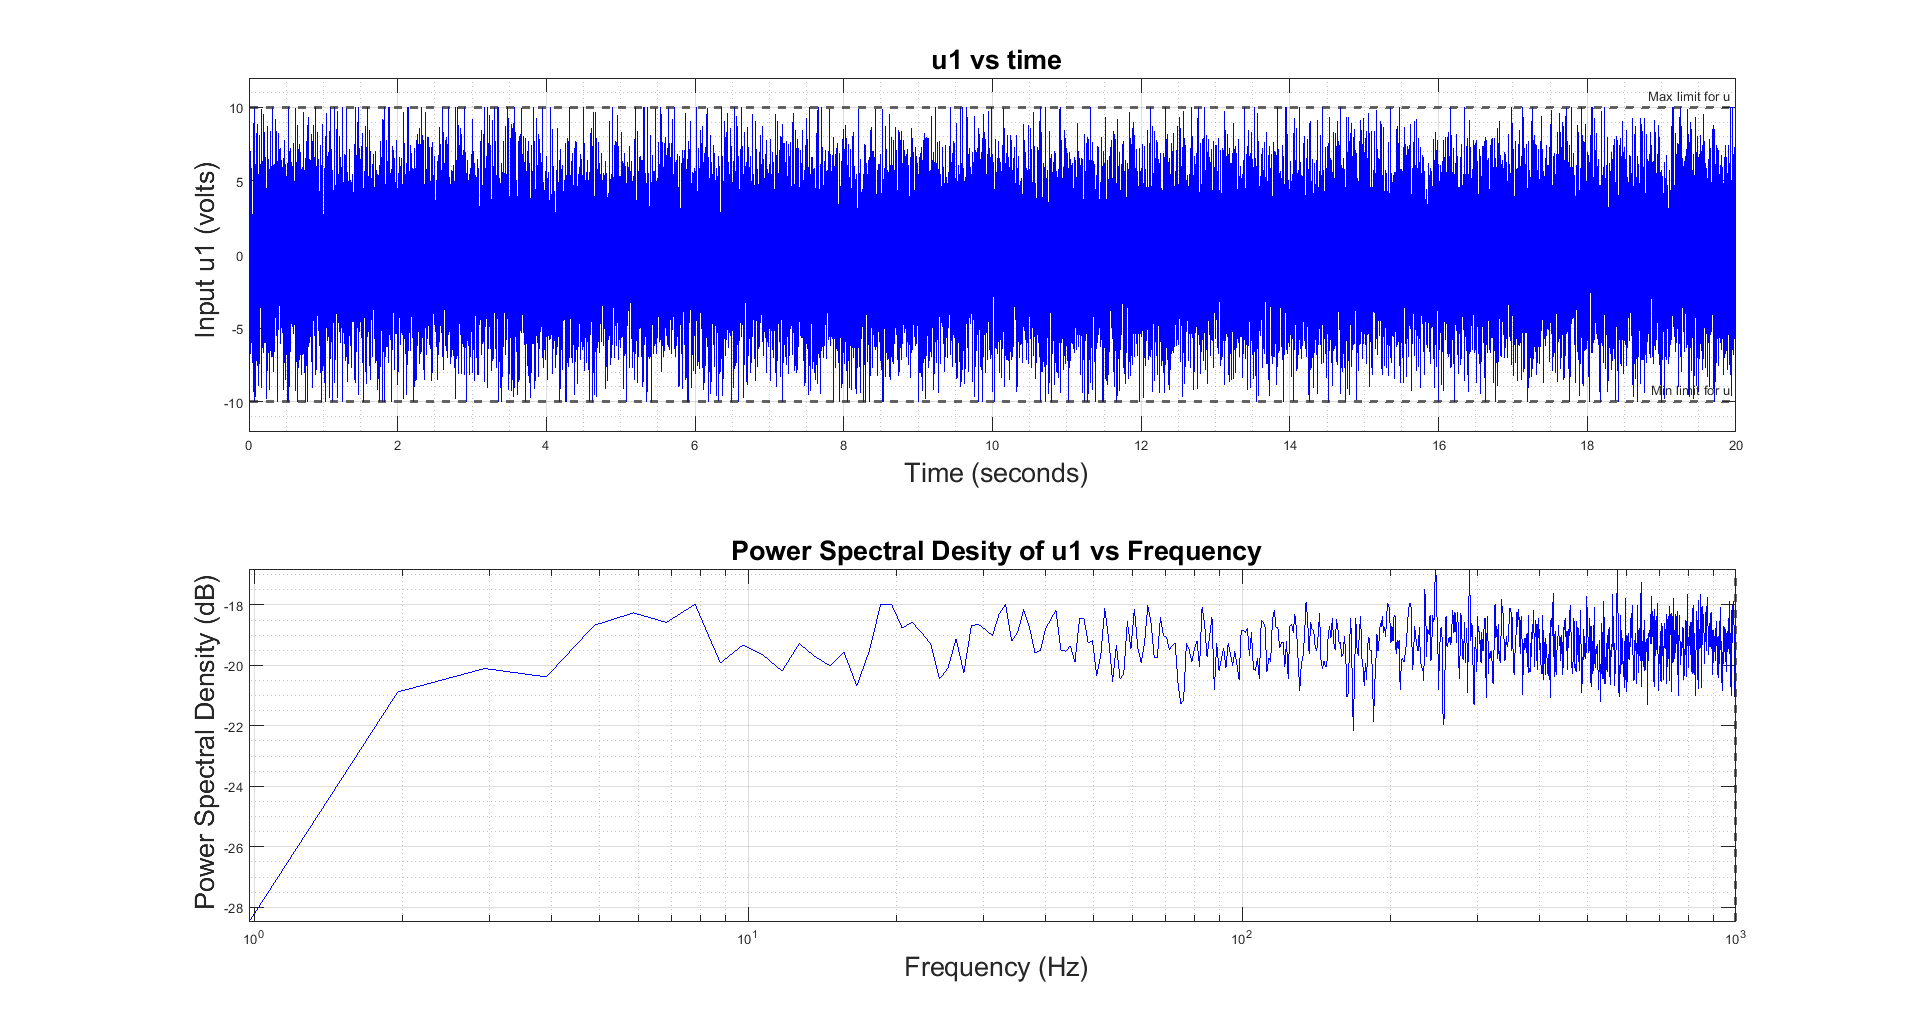

% frequency_min  = 1;     % Hz (given)
% f_s = 2000;             % Sample Rate, Hz (given)
% T_s = 1/f_s;            % Sample Time Period, s
% nyquist = f_s/2;        % Nyquist Frequency, Hz
% 
% % Our sample rate is 2000 samples/sec, and we can only have 20 sec of data
% % So batch size is 2000*20 = 40,000 samples
% batch_max = f_s*20;     % Largest bin size allowed by the plant
% N = batch_max;          % DOES NOT NEED TO BE POWER OF 2
%  
% nfft_approximate = f_s/(frequency_min); % Gives us 2000, let's increase it to 2048 (2^11)
% nfft = 2^8;                           % Calculate New Frequency min, (2^11 = 1028)
% Frequency_min_new = f_s/(nfft);

%%%% Professor's solution of above
f_s = 2000;             % Sample Rate, Hz (given)
T_s = 1/f_s;            % Sample Time Period, s
nyquist = f_s/2;        % Nyquist Frequency, Hz
Fbin = 1;               % Desired frequency bin resolution
power_of_2 = nextpow2(f_s/Fbin);


nfft = 2^power_of_2;
Fbin = f_s/nfft;
NMAX = 40000;
N = NMAX/1;

%%%%%%%


window = nfft;
overlap = window/2;
% fr_range = Frequency_min_new:Frequency_min_new:f_s; % 2048 data points

% Generate random noise samples with N samples over
% (1/Frequency_min_new)seconds
u = randn(1, N);    % generates an 1-by-N matrix of noise samples in volts.
% u = randn(N,1);
u1 = u(1,:);
% u1 = u(:,1);

% Filtering Input Signal u1 with a highpass filter
% Normalized Passband frequency of 2 Hz
% Steepness value of 0.5
u1 = 3.5*highpass(u1, 2, f_s, 'Steepness', 0.5);


%%%%%%% Professor's solution 
% [num, den] = butter(3, [1 850]/(f_s/2));
% u1 = 3.5*filter(num1, den1, u1);



% Clipping excitation input above 10 Hz and below -10 Hz
j = find(u1>10);
u1(j) = 10;
k = find(u1 <- 10);
u1(k) = -10;


% PWELCH, Welch's power spectral density estimate
[pxx_u1, Fr] = pwelch(u1, window, overlap, nfft, f_s);

% dB conversion
pxx_u1_dB = 10*log10(pxx_u1);

% Time
% t = T_s*(1:length(u1));
t = T_s*(1:N);

% [S_u1u1, Fr] = cpsd(u1, u1, window, overlap, nfft, f_s);             % PSD of u1

% Plots
figure()
subplot(2, 1, 1)
plot(t,u1,'b'); 
hold on
grid on
grid minor
axis tight
yline(10,'--','Max limit for u','LineWidth',2);
yline(-10,'--','Min limit for u','LineWidth',2);
xlim([0, max(t)]); 
ylim([-12 12]);
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Input u1 (volts)', 'interpreter', 'tex'); 
title('\fontsize{20} u1 vs time', 'interpreter', 'tex');
hold off

% subplot(2, 1, 2)
% semilogx(Fr,10*log10(S_u1u1),'b'); 
% grid on
% grid minor
% axis tight
% xline(nyquist,'--','Nyquist','LineWidth',2);
% xlim([Frequency_min_new, nyquist]); 
% xlabel('\fontsize{20} Frequency (Hz)', 'interpreter', 'tex'); 
% ylabel('\fontsize{20} Power Spectral Density (dB)', 'interpreter', 'tex'); 
% title('\fontsize{20} Power Spectral Desity of u1 vs Frequency', 'interpreter', 'tex');

subplot(2, 1, 2)
semilogx(Fr,pxx_u1_dB,'b'); 
grid on
grid minor
axis tight
xline(nyquist,'--','Nyquist','LineWidth',2);
% xlim([Frequency_min_new, nyquist]); 
xlabel('\fontsize{20} Frequency (Hz)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Power Spectral Density (dB)', 'interpreter', 'tex'); 
title('\fontsize{20} Power Spectral Desity of u1 vs Frequency', 'interpreter', 'tex');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Section 2**

Apply the excitation to the dynamic system (s20_plant) to obtain the noisy response signals.  Estimate and display the SNR (dB) for each of the two paths.  

**HINT**:  Your System ID results will be much better if you attempt to maximize the SNR; however, you are not allowed to saturate (i.e. clip) either the excitations or the responses!

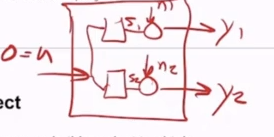

% Calculating Magnitude of noise without any input i.e. turning off input u
No_Input = zeros(1, N);             % 1 x3 2,768 vector
y_No_input = s20_plant(No_Input);   % 2 x 32,768 vector

y = s20_plant(u1); % MAKE SURE THAT THE SATURATION DOES NOT GO ABOVE 0.1%

*** Warning:  Response saturated 30/40000 samples (0.075%)


% y = s20_plant(u1');
y1 = y(1,:);         % 1x32,768 vector
y2 = y(2,:);         % 1x32,768 vector

% Noise variance for outputs 1 and 2
Noise_Variance_y1 = var(y_No_input(1,:));
Noise_Variance_y2 = var(y_No_input(2,:));

Input_Variance_u1 = var(u1);

SNR_u1_To_y1 = 10*log10((std(y1)^2 - std(y_No_input(1,:))^2)/std(y_No_input(1,:))^2);
SNR_u1_To_y2 = 10*log10((std(y2)^2 - std(y_No_input(2,:))^2)/std(y_No_input(2,:))^2);

fprintf('SNR for path u1 to y1 is: %f dB', SNR_u1_To_y1);

SNR for path u1 to y1 is: 23.315819 dB

fprintf('SNR for path u1 to y2 is: %f dB', SNR_u1_To_y2);

SNR for path u1 to y2 is: 23.521017 dB

## **Section 3**

Compute and plot the properly scaled power spectrum for the responses.  On these same plots, compute and plot the properly scaled power spectrum for the noise signals.  Demonstrate that the measured sensor responses do not saturate the ADC’s by plotting the responses in the time domain.  The spectrum of y1 and n1 must be in one axes, and the spectrum of y2 and n2 must be in a second axes.  The time series plot of y1 and n1 must be in one axes, and the time series plot of y2 and n2 must be in a second axes.  You must have four separate axes in a 2x2 grid on a single figure. 

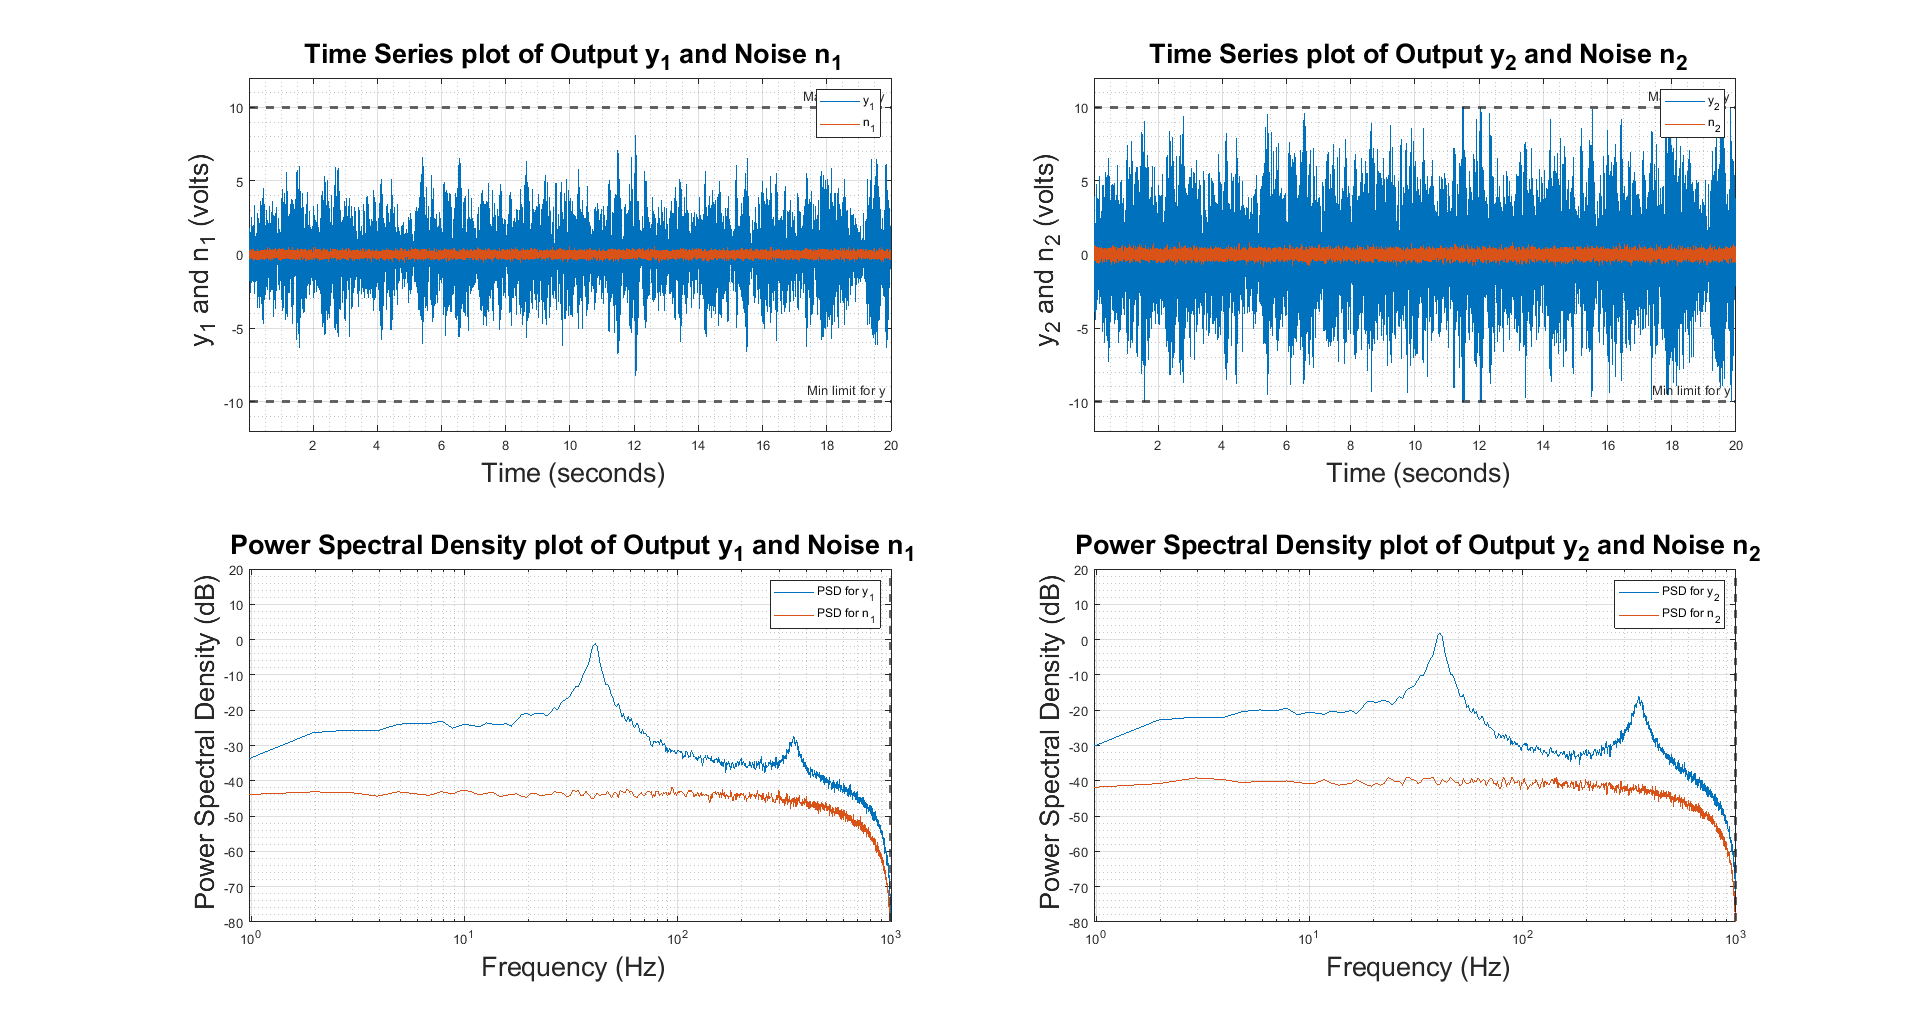

%----------------------------------------------------------------
%%%%%%%%%%%% Noise Signals without input u1 %%%%%%%%%%%%%%%%%%%%
%----------------------------------------------------------------

n1 = y_No_input(1,:);
n2 = y_No_input(2,:);


%-------------------------------------------------------------
%%%%%%%%%%%% Cross power spectral density %%%%%%%%%%%%%%%%%%%%
%--------------------------------------------------------------

% uses nfft sampling points to calculate the discrete Fourier transform.
% Note: Each PSD is a 1025 X 1 vector because of nfft (2^11 = 1024, + 1)
[S_y1y1] = cpsd(y1, y1, window, overlap, nfft, f_s);             % PSD y1
[S_y2y2] = cpsd(y2, y2, window, overlap, nfft, f_s);             % PSD y2
[S_n1n1] = cpsd(n1, n1, window, overlap, nfft, f_s);             % PSD n1
[S_n2n2] = cpsd(n2, n2, window, overlap, nfft, f_s);             % PSD n2
[S_u1u1] = cpsd(u1, u1, window, overlap, nfft, f_s);             % PSD of u1

% To estimate the Transfer Function of open loop path
[S_y1u1] = cpsd(y1, u1, window, overlap, nfft, f_s);             % PSD for path u1 to y1
[S_y2u1] = cpsd(y2, u1, window, overlap, nfft, f_s);             % PSD for path u1 to y2

%--------------------------------------------------------------------------
%%%%%%%%%%%%%%%%%%%%%%%% Plot results %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%--------------------------------------------------------------------------
figure()
subplot(2, 2, 1)
plot(t, y1); 
hold on
grid on
grid minor
axis tight
plot(t, n1);
% xlim([0, max(t)]); 
ylim([-12 12]);
yref1 = yline(10,'--','Max limit for y','LineWidth',2);
yref2 = yline(-10,'--','Min limit for y','LineWidth',2);
legend('y_1', 'n_1');
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y_1 and n_1 (volts)', 'interpreter', 'tex'); 
title('\fontsize{20} Time Series plot of Output y_1 and Noise n_1', 'interpreter', 'tex');
hold off

subplot(2, 2, 2)
plot(t, y2); 
hold on
grid on
grid minor
axis tight
plot(t, n2);
% xlim([0, max(t)]); 
ylim([-12 12]);
yref1 = yline(10,'--','Max limit for y','LineWidth',2);
yref2 = yline(-10,'--','Min limit for y','LineWidth',2);
legend('y_2', 'n_2');
xlabel('\fontsize{20} Time (seconds)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} y_2 and n_2 (volts)', 'interpreter', 'tex'); 
title('\fontsize{20} Time Series plot of Output y_2 and Noise n_2', 'interpreter', 'tex');
hold off


subplot(2, 2, 3)
semilogx(Fr, 10*log10(abs(S_y1y1))); 
hold on
grid on
grid minor
axis tight
semilogx(Fr, 10*log10(abs(S_n1n1))); 
xref1 = xline(nyquist,'--','Nyquist','LineWidth',2);
% xlim([Frequency_min_new, nyquist]); 
ylim([-80 20]);
legend('PSD for y_1', 'PSD for n_1');
xlabel('\fontsize{20} Frequency (Hz)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Power Spectral Density (dB)', 'interpreter', 'tex'); 
title('\fontsize{20} Power Spectral Density plot of Output y_1 and Noise n_1', 'interpreter', 'tex');
hold off

subplot(2, 2, 4)
semilogx(Fr, 10*log10(abs(S_y2y2))); 
hold on
grid on
grid minor
axis tight
semilogx(Fr, 10*log10(abs(S_n2n2))); 
xref1 = xline(nyquist,'--','Nyquist','LineWidth',2);
% xlim([Frequency_min_new, nyquist]); 
ylim([-80 20]);
legend('PSD for y_2', 'PSD for n_2');
xlabel('\fontsize{20} Frequency (Hz)', 'interpreter', 'tex'); 
ylabel('\fontsize{20} Power Spectral Density (dB)', 'interpreter', 'tex'); 
title('\fontsize{20} Power Spectral Density plot of Output y_2 and Noise n_2', 'interpreter', 'tex');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Section 4**

Apply an appropriate frequency domain estimation technique from the course to estimate frequency response functions for each open-loop path.  Estimate the coherence associated with each path.  This data will be plotted in a later section. 

#### FRF Estimate, Using** H1 estimation method**:

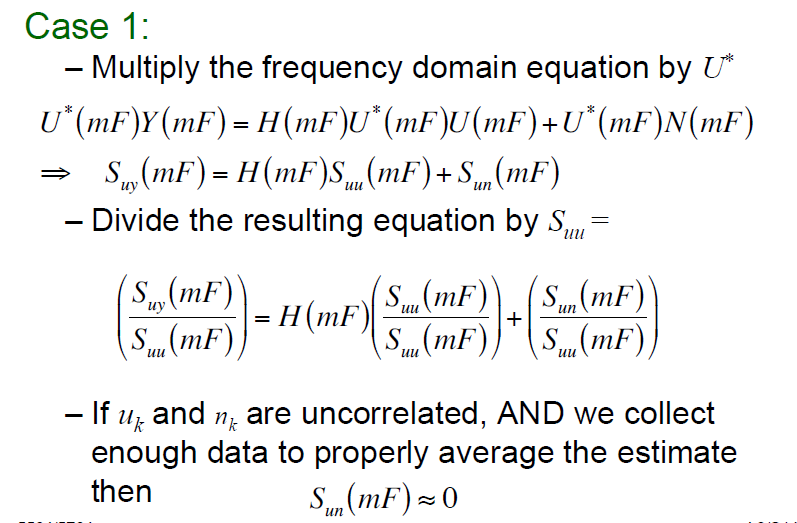                  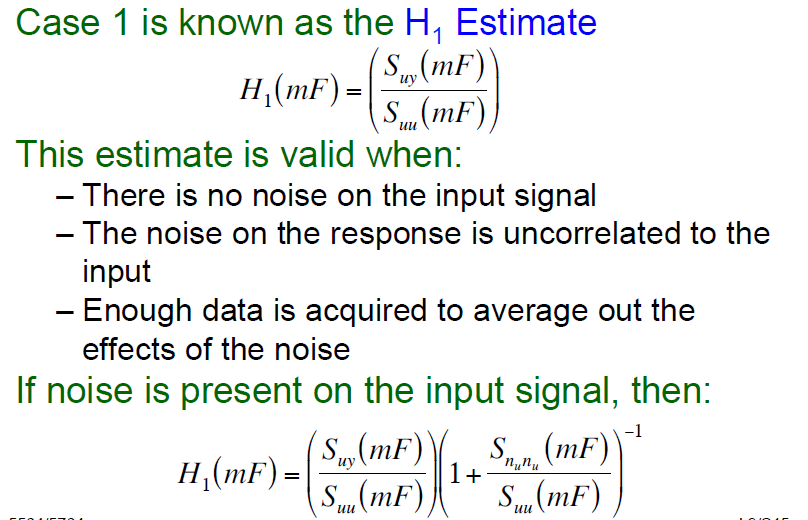

Coherence of two signals x & y $\Longrightarrow \;$`abs(Sxy)^2/(Sx*Sy)`

%---------------------------------------------
%%%%%%%%%%%% FRF Estimate %%%%%%%%%%%%%%%%%%%%
%---------------------------------------------
H1_estimate_y1u1 = S_y1u1 ./ S_u1u1;                    % path u1 to y1, 1025 x 1
H1_estimate_y2u1 = S_y2u1 ./ S_u1u1;                    % path u1 to y2, 1025 x 1

%--------------------------------------------------------------------
%%%%%%%%%%%% Coherence Calculation for each path %%%%%%%%%%%%%%%%%%%%
%--------------------------------------------------------------------
[coherence_y1u1] = mscohere(u1, y1, window, overlap, nfft, f_s);
[coherence_y2u1] = mscohere(u1, y2, window, overlap, nfft, f_s);

## **Section 5**

Use the **invfreqz** function to estimate discrete time transfer function models for each of the two paths in the open-loop plant.  You must choose exactly the same number of poles for each path.  Store your estimated numerator and denominator polynomials in a Matlab cell array with appropriate dimensions to match the dynamic system dimensions.  Convert the numerator and denominator cell arrays into a discretetime transfer function LTI object.  Convert this LTI object into a minimum realization using the **minreal** function. 

Note:

If F = 1 Hz, $\omega$(Angular Frequency) = 2*$\Pi$*F = 2*$\Pi$ (rad/s)

%------------------------------------------------------------------------------------------------------
%%%%%%%%%%%% Identify discrete-time filter parameters from frequency response data %%%%%%%%%%%%%%%%%%%%
%------------------------------------------------------------------------------------------------------
% [b,a] = invfreqz(h,w,n,m, wt)
% returns the real numerator and denominator coefficient vectors b and a of the transfer function h.
% INPUT ARGUMENTS:
% h -- Frequency response, specified as a vector
% w -- Angular frequencies at which h is computed, specified as a vector.
% n, m -- Desired order of the numerator and denominator polynomials, specified as positive integer scalars.
% wt -- Weighting factors, specified as a vector. wt is a vector of weighting factors that is the same length as w.

% Numerator order determines the number of zeros, Denominator determines
% the number of poles
n11 = 7; 
n21 = n11;
d11 = n11;   % Numerator, denominator poles for path u1 to y1
d21 = n21;   % Numerator, denominator poles for path u1 to y2

[B11,A11] = invfreqz(H1_estimate_y1u1, pi.*Fr/(f_s/2) , n11, d11, coherence_y1u1);   % Path u1 to y1, 1xn21 and 1xd21 vectors
[B21,A21] = invfreqz(H1_estimate_y2u1, pi.*Fr/(f_s/2) , n21, d21, coherence_y2u1);   % Path u1 to y2, 1xn21 and 1xd21 vectors

%---------------------------------------------
%%%%%%%%%%%% Using Freqz %%%%%%%%%%%%%%%%%%%%
%---------------------------------------------
% Used in Section 10, to plot FRF invfreqz from Section 5
[Section5_path1_Freqz] = freqz(B11,A11, Fr, f_s);
[Section5_path2_Freqz] = freqz(B21,A21, Fr, f_s);

%-----------------------------------------------------------------
%%%%%%%%%%%% Transfer Function representation %%%%%%%%%%%%%%%%%%%%
%-----------------------------------------------------------------
% Need to have T_s for discrete time transfer function
% METHOD 1
H11 = tf(B11,A11,T_s);          % Path u1 to y1
H21 = tf(B21,A21,T_s);          % Path u1 to y2

H = [H11; H21];                  % Combining the 2 Transfer Functions in a single vector
% Converting to state space form 
H_ss = ss(H);                    % Combined SS for the 2 Transfer Functions

%----------------------------------------------------
%%%%%%%%%%%% Minimum Realization %%%%%%%%%%%%%%%%%%%%
%-----------------------------------------------------
H11_minreal = minreal(H11);           % Path u1 to y1
H21_minreal = minreal(H21);           % Path u1 to y2
H_minreal = minreal(H);               % Combined

## **Section 6**

Convert the minimum realization transfer function LTI object from Section 5 into a discrete-time state-space LTI object.  Input the discrete-time state-space model to the **balreal** function in Matlab to generate a balanced realization and extract the Hankel singular values for the estimated model.  Plot the Hankel singular values in a bar chart to determine an appropriate cutoff threshold for pruning non-contributing modes from the resulting LTI state-space object.  Use the **modred** function in Matlab to generate a reduced order LTI discrete time state-space model.  Read the Matlab help for the minreal, balreal, and modred functions to learn more about how these functions work. 

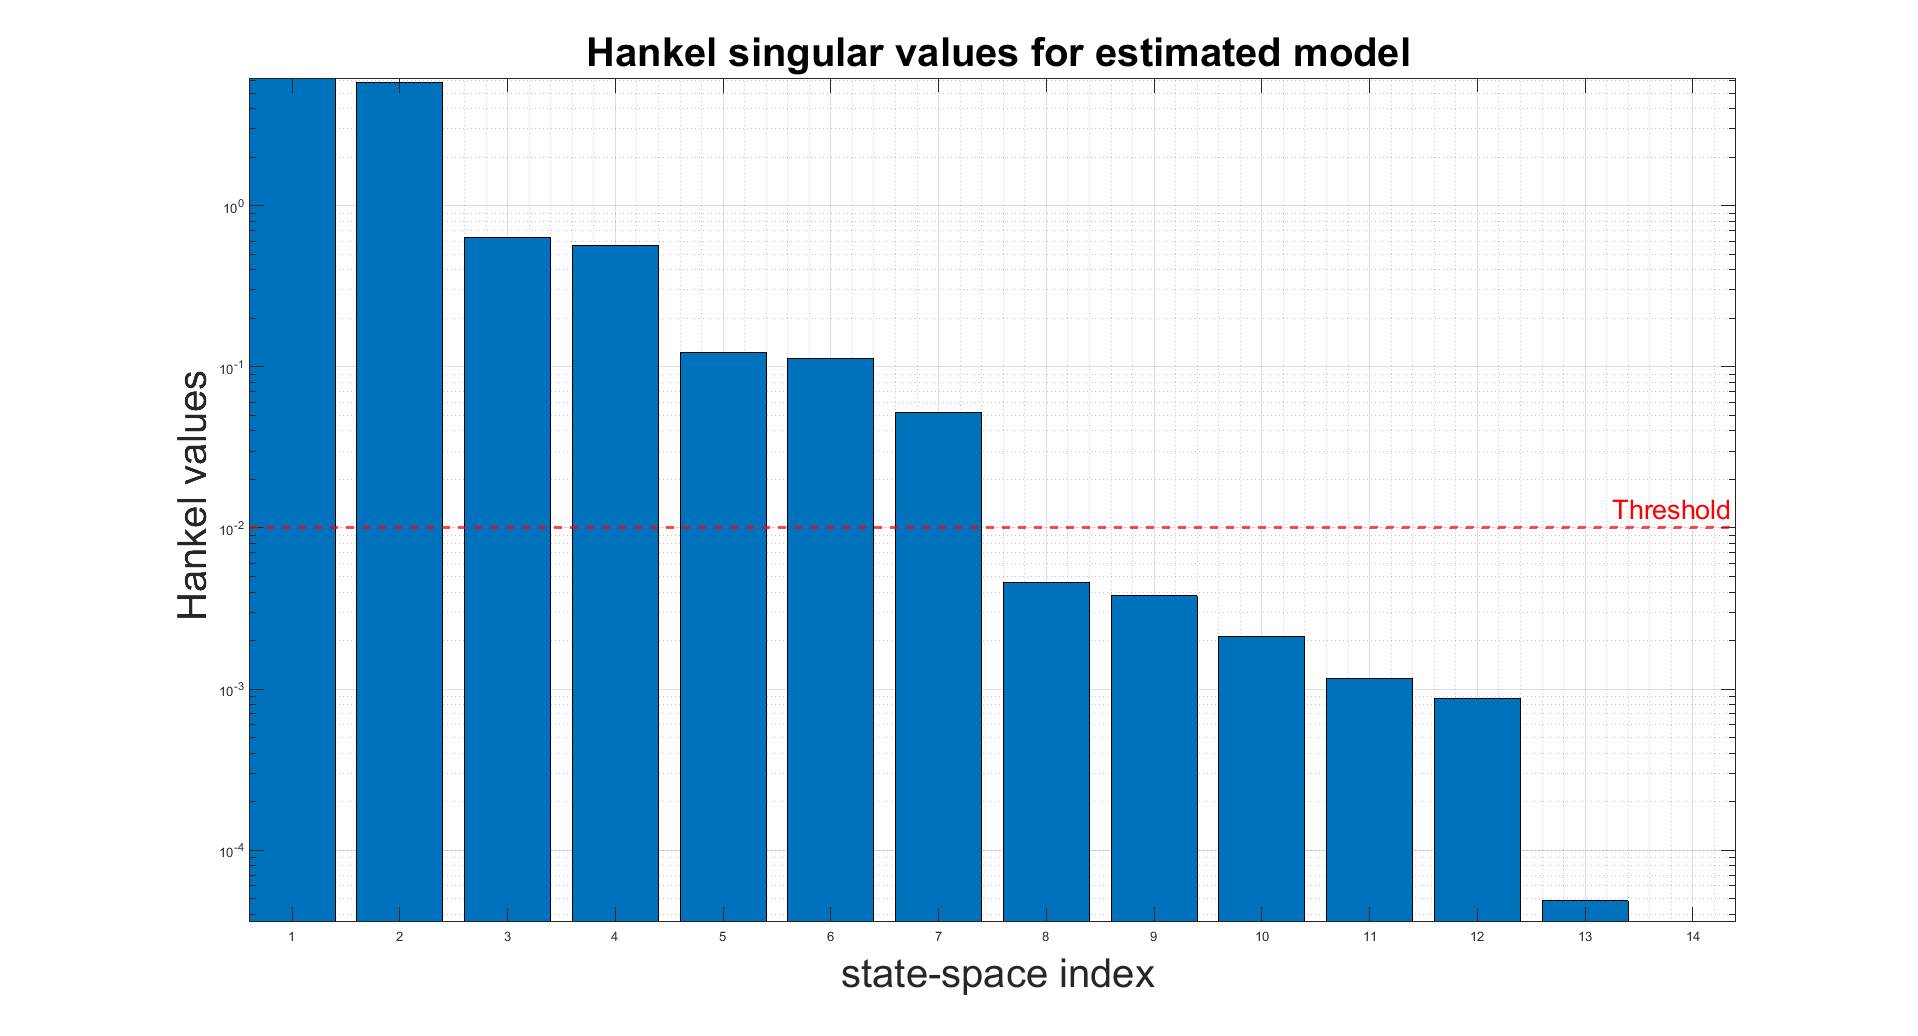

%------------------------------------------------------
%%%%%%%%%%%% State Space LTI object %%%%%%%%%%%%%%%%%%%%
%-------------------------------------------------------
H_ss_minreal = ss(H_minreal);           % Combined

% NOTE: Use only combined State Space Model After this:
%------------------------------------------------------
%%%%%%%%%%%% Balanced Realization %%%%%%%%%%%%%%%%%%%%
%-------------------------------------------------------
% G containing the diagonal of the balanced Gramian
[H_balreal,G] = balreal(H_ss_minreal);          % Combined


% Based on viewing the Hankel G values
% A good indicator of threshold is drop by 2 orders (10x10 or 100)
% In the below Graph i can see a drop of about 1.5+ order from 7th state to
% 8th state
threshold =  1e-2;                % To be decided

%------------------------------------------------
%%%%%%%%%%%% Plot Bar chart %%%%%%%%%%%%%%%%%%%%
%------------------------------------------------

figure() 
bar(G);    
set(gca, 'YScale', 'log'); % Setting the y scale to be logarithmic 
grid on 
hold on 
grid minor
axis tight
% also plot where you choose to cutoff 
Cutoff = yline(threshold,'--','\fontsize{20} Threshold','LineWidth',2);
Cutoff.Color = 'red';
hold off 
xlabel('\fontsize{30} state-space index', 'interpreter', 'tex'); 
ylabel('\fontsize{30} Hankel values', 'interpreter', 'tex'); 
title('\fontsize{30} Hankel singular values for estimated model', 'interpreter', 'tex'); 

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

%--------------------------------------------------------------------
%%%%%%%%%%%% Reduced Order LTI State Space Model %%%%%%%%%%%%%%%%%%%%
%--------------------------------------------------------------------
eliminate = (G<(threshold)); % Small entries of G are negligible states 
H_ss_reduced = modred(H_balreal, eliminate, 'Truncate'); % Truncate to remove effect of poles from removed states

save Midterm_OL_SS_LTI_Model H_ss_reduced

## **Section 7**

Compute the z-domain eigenvalues (poles) of the LTI object result from Section 6.  Compute the natural frequencies with units of Hz, and the damping ratios associated with every eigenvalue.

%-------------------------------------------------------------------------
%%%%%%%%%%%% Poles Information for Reduced LTI object %%%%%%%%%%%%%%%%%%%%
%--------------------------------------------------------------------------
disp(' Reduced-Order State-Space Pole Information: ');

 Reduced-Order State-Space Pole Information: 


[Wn_red, Zeta_red, Poles_red] = damp(H_ss_reduced);
Wn_Hz = Wn_red/(2*pi);

% Displaying in a Table format
T = table(Wn_Hz, Zeta_red, Poles_red);
T.Properties.VariableNames = {'Natural_Frequency_Wn_in_Hertz','Damping_Ratio_zeta','Poles_p'};
disp(T);

    Natural_Frequency_Wn_in_Hertz    Damping_Ratio_zeta         Poles_p     
    _____________________________    __________________    _________________

               40.503                     0.042689          0.98656+0.1261i 
               40.503                     0.042689          0.98656-0.1261i 
               40.689                     0.043762          0.98632+0.12665i
               40.689                     0.043762          0.98632-0.12665i
               351.67                     0.053141          0.42499+0.84178i
               351.67                     0.053141          0.42499-0.84178i
               778.78                            1         0.086586+0i      



## **Section 8**

Compute the eigenvalues (poles) for both of the discrete time open-loop transfer function models you estimated in Section 5.  Use the **zgrid** function in Matlab to generate a z-domain grid, and then plot each set of poles on this plot using clearly labeled markers for each of the estimated path models.  Do NOT plot the zeros!  There should be three sets of poles on the plot:  one for the y1 path (Section 5), one for the y2 path (Section 5), and one for the final discrete-time state-space model (Section 6).  All markers should be the same for the poles associated with the same path.  You must use the axis equal command to scale the plot correctly.

 If your models are accurate enough, you should see tightly concentrated “clusters” of poles from each of the paths in the z-plane.  Clusters indicate pole locations that are common between paths.  Technically both paths should have the exact same poles since they are all associated with the same dynamic system.  This may not be the case for your solution because the estimation process is a numerical approximation for each individual path.

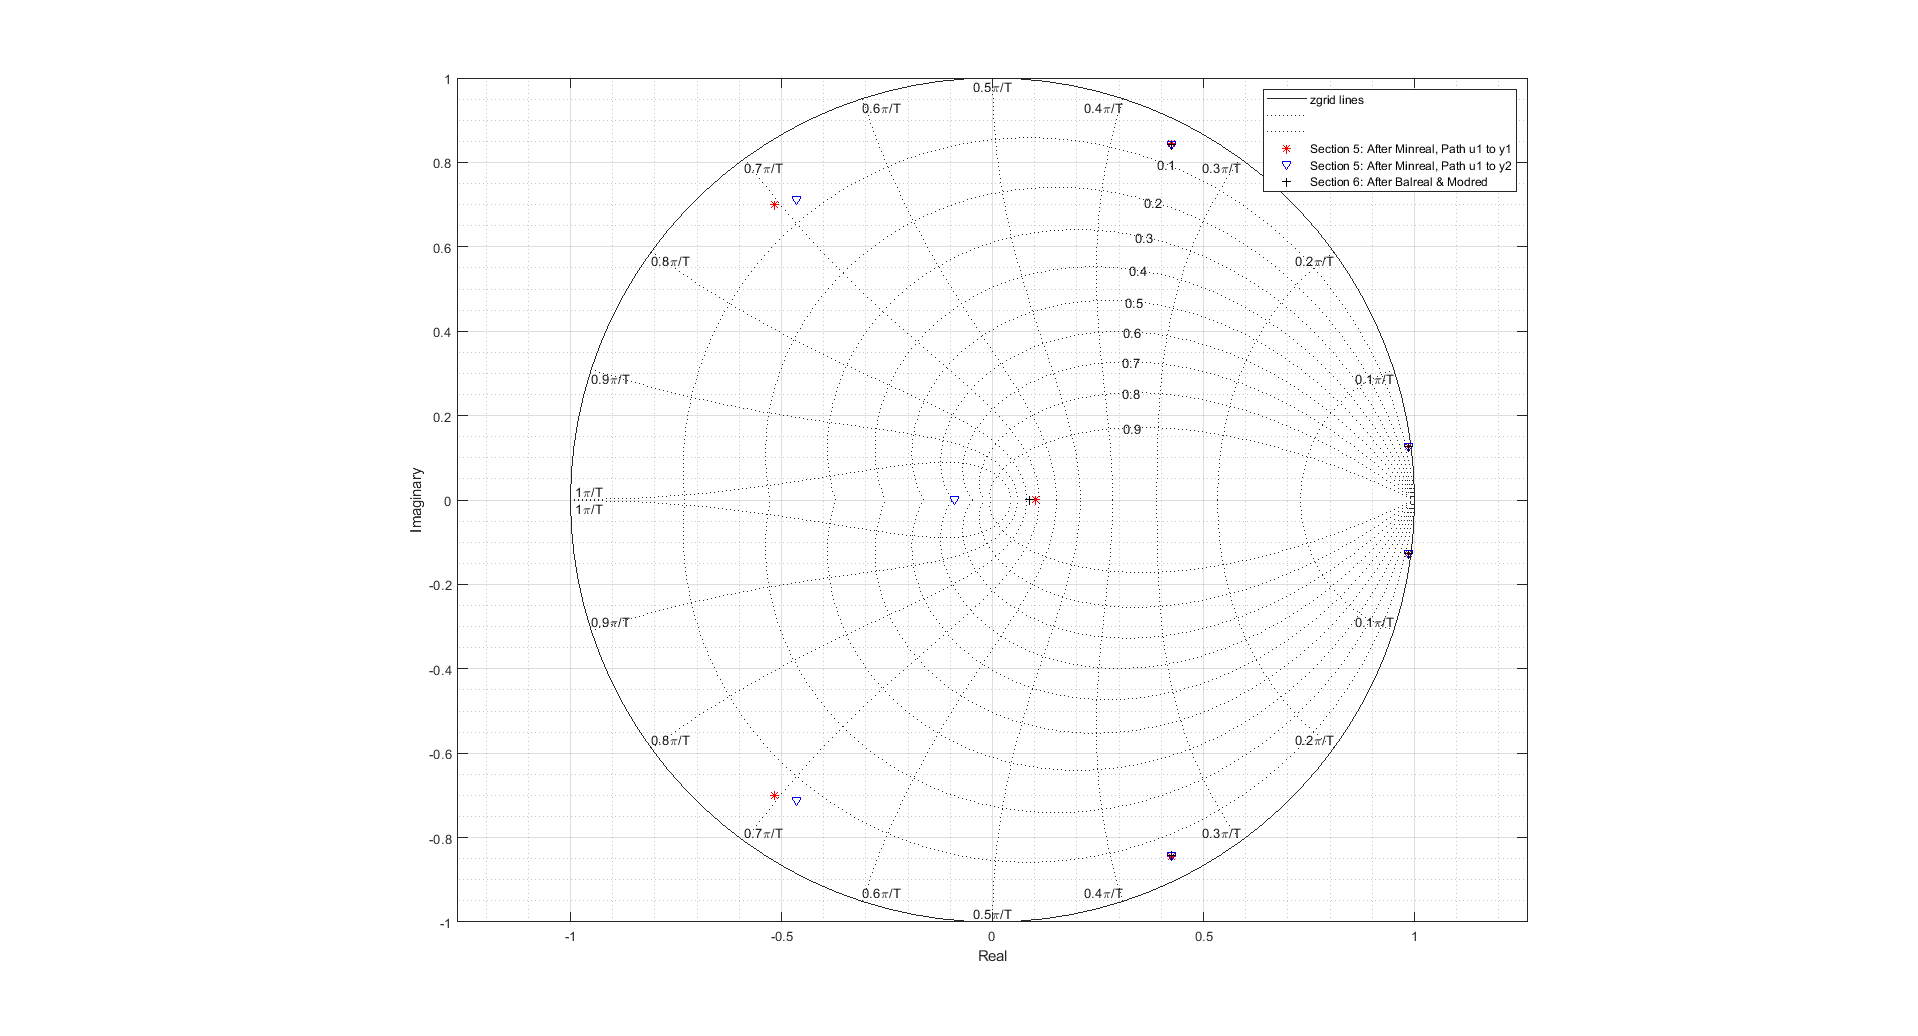

%----------------------------------------------------------------------------------------------
%%%%%%%%%%%% Poles information of Minimum Realization LTI State Space Model %%%%%%%%%%%%%%%%%%%%
%-----------------------------------------------------------------------------------------------
[Wn11_minreal, Zeta11_minreal, Poles11_minreal] = damp(ss(H11_minreal));         % Section 5, Minreal Applied, Path u1 to y1
[Wn21_minreal, Zeta21_minreal, Poles21_minreal] = damp(ss(H21_minreal));         % Section 5, Minreal Applied, Path u1 to y2
[Wn_minreal, Zeta_minreal, Poles_minreal] = damp(H_ss_minreal);                 % Section 5, Minreal Applied, Combined

% Note: H_ss_reduced in Section 6 is the Reduced Order of Balanced Realization of LTI State Space model
%-----------------------------------------------------------
%%%%%%%%%%%% Plot Zgrid with only poles %%%%%%%%%%%%%%%%%%%%
%-----------------------------------------------------------

figure()
zgrid(2*pi*T_s, 'new');
grid on
grid minor
hold on
scatter(real(Poles11_minreal), imag(Poles11_minreal), 'red', '*');    % Section 5: After Minreal, Path u1 to y1
scatter(real(Poles21_minreal), imag(Poles21_minreal), 'blue', 'V');   % Section 5: After Minreal, Path u1 to y2
scatter(real(Poles_red), imag(Poles_red), 'k', '+');                  % Section 6, Final SS model; Reduced Order of Balanced Realization
axis equal
legend('zgrid lines', '', '', 'Section 5: After Minreal, Path u1 to y1', 'Section 5: After Minreal, Path u1 to y2',  'Section 6: After Balreal & Modred');
xlabel('Real');
ylabel('Imaginary');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

## **Section 9**

Compute the frequency response of the final discrete-time state-space LTI object result from Section 5 using the **freqresp** function.  Compute the frequency response of the final discrete-time state-space LTI object result from Section 6 using the freqresp function

%---------------------------------------------------
%%%%%%%%%%%% Frequency Response %%%%%%%%%%%%%%%%%%%%
%----------------------------------------------------
[Freqresp_No_minreal] = freqresp(H_ss, Fr, 'Hz');                % Section 5: Before Minreal
[Freqresp_red] = freqresp(H_ss_reduced, Fr, 'Hz');                % Section 6, Final SS model; Reduced Order of Balanced Realization

## **Section 10**

Compare the results of your estimation in the frequency domain by generating dB magnitude vs. log frequency and phase (degrees) vs. log frequency plots (a.k.a. Bode diagrams) for each path.  You must directly plot the estimated frequency response from Section 4 on top of the frequency response from the transfer function results in Section 5 and the frequency response from the state-space results in Section 6.  There will be two figures and on each figure there will be three axes displayed in a 3x1 grid:  one for coherence, one for phase, and one for magnitude.  All three frequency response curves must be properly labeled and displayed for visual inspection. 

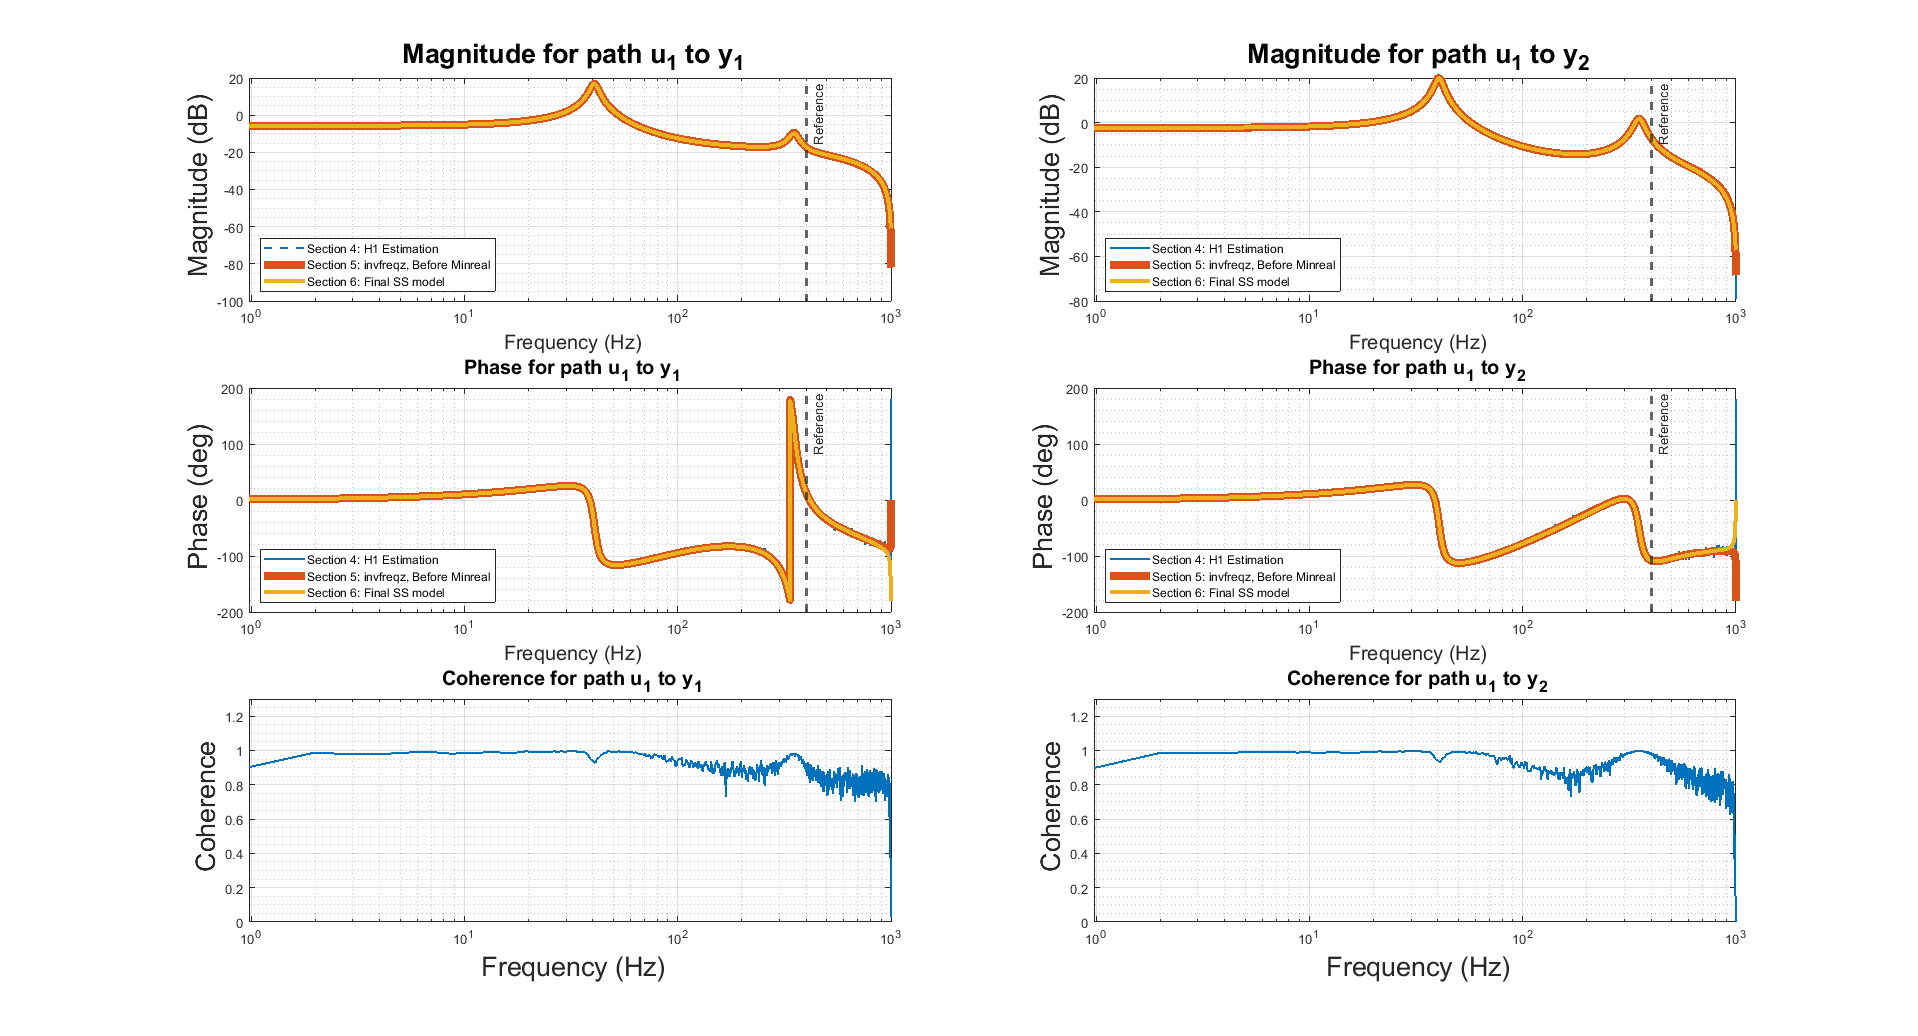

% Decibel Conversion for Magnitude:
Freqresp_estimate11_dB = 20*log10(abs(H1_estimate_y1u1));              % Section 4, Estimation, u1 to y1
Freqresp_estimate21_dB = 20*log10(abs(H1_estimate_y2u1));              % Section 4, Estimation, u1 to y2
Freqresp_No_minreal_dB = 20*log10(abs(Freqresp_No_minreal));           % Section 5: Before Minreal
Freqresp_red_dB = 20*log10(abs(Freqresp_red));                         % Section 6, Final SS model; Reduced Order of Balanced Realization

% Degree Conversion for Phase:
Freqresp_estimate11_deg = (180/pi)*angle(H1_estimate_y1u1);            % Section 4, Estimation, u1 to y1
Freqresp_estimate21_deg = (180/pi)*angle(H1_estimate_y2u1);            % Section 4, Estimation, u1 to y2
Freqresp_No_minreal_deg = (180/pi)*angle(Freqresp_No_minreal);        % Section 5: Before Minreal
Freqresp_red_deg = (180/pi)*angle(Freqresp_red);                       % Section 6, Final SS model; Reduced Order of Balanced Realization

% Dividing the data for each path:
%------------------------------------------------------
%%%%%%%%%%%% Section 4, Estimation %%%%%%%%%%%%%%%%%%%%
%------------------------------------------------------
Freqresp_estimate11_dB = squeeze(Freqresp_estimate11_dB(:,1));
Freqresp_estimate21_dB = squeeze(Freqresp_estimate21_dB(:,1));

Freqresp_estimate11_deg = squeeze(Freqresp_estimate11_deg(:,1));
Freqresp_estimate21_deg = squeeze(Freqresp_estimate21_deg(:,1));


%------------------------------------------------------
%%%%%%%%%%%% Section 5, No Minreal %%%%%%%%%%%%%%%%%%%%
%------------------------------------------------------
Freqresp_No_minreal_dB11 = squeeze(Freqresp_No_minreal_dB(1,1,:));       % Path u1 to y1
Freqz_No_minreal_dB11 = 20*log10(abs(Section5_path1_Freqz));             % Using Freqz, , u1 to y1
Freqz_No_minreal_dB21 = 20*log10(abs(Section5_path2_Freqz));             % Using Freqz, , u1 to y2
Freqresp_No_minreal_dB21 = squeeze(Freqresp_No_minreal_dB(2,1,:));       % Path u1 to y2

Freqresp_No_minreal_deg11 = squeeze(Freqresp_No_minreal_deg(1,1,:));     % Path u1 to y1
Freqz_No_minreal_deg11 = (180/pi)*angle(Section5_path1_Freqz);           % Using Freqz, , u1 to y1
Freqz_No_minreal_deg21 = (180/pi)*angle(Section5_path2_Freqz);           % Using Freqz, , u1 to y2
Freqresp_No_minreal_deg21 = squeeze(Freqresp_No_minreal_deg(2,1,:));     % Path u1 to y2

%-------------------------------------------------------
%%%%%%%%%%%%% Section 6, Final SS model %%%%%%%%%%%%%%%%
%-------------------------------------------------------
Freqresp_red_dB11 = squeeze(Freqresp_red_dB(1,1,:));                      % Path u1 to y1
Freqresp_red_dB21 = squeeze(Freqresp_red_dB(2,1,:));                      % Path u1 to y2

Freqresp_red_deg11 = squeeze(Freqresp_red_deg(1,1,:));                    % Path u1 to y1
Freqresp_red_deg21 = squeeze(Freqresp_red_deg(2,1,:));                    % Path u1 to y2

%-------------------------------------------------------------------------
%%%%%%%%%%%% Plot Coherence, Phase & Mag for each path %%%%%%%%%%%%%%%%%%%%
%--------------------------------------------------------------------------

figure()
subplot(3,2,1)
semilogx(Fr, Freqresp_estimate11_dB, 'LineStyle', '--', 'LineWidth', 1.5);      % Section 4: H1 Estimate, Path u1 to y1
grid on
grid minor
hold on
semilogx(Fr, Freqz_No_minreal_dB11, 'LineWidth', 6);       % Section 5: invFreqz, Before Minreal, Path u1 to y1
semilogx(Fr, Freqresp_red_dB11, 'LineWidth', 3);            % Section 6, Reduced Order SS, Path u1 to y1
xref1 = xline(400,'--','Reference','LineWidth',2);
l1 = legend('Section 4: H1 Estimation', 'Section 5: invfreqz, Before Minreal', 'Section 6: Final SS model', 'interpreter', 'tex');
l1.Location = 'southwest';
title('\fontsize{20} Magnitude for path u_1 to y_1', 'interpreter', 'tex');
ylabel('\fontsize{20} Magnitude (dB)', 'interpreter', 'tex');
xlabel('\fontsize{15} Frequency (Hz)', 'interpreter', 'tex');
hold off

subplot(3,2,2)
semilogx(Fr, Freqresp_estimate21_dB, 'LineWidth', 1.5);      % Section 4: H1 Estimate, Path u1 to y2
grid on
grid minor
hold on
semilogx(Fr, Freqz_No_minreal_dB21, 'LineWidth', 6);       % Section 5: invFreqz, Before Minreal, Path u1 to y2
semilogx(Fr, Freqresp_red_dB21, 'LineWidth', 3);            % Section 6, Reduced Order SS, Path u1 to y2
xref1 = xline(400,'--','Reference','LineWidth',2);
l1 = legend('Section 4: H1 Estimation', 'Section 5: invfreqz, Before Minreal', 'Section 6: Final SS model', 'interpreter', 'tex');
l1.Location = 'southwest';
title('\fontsize{20} Magnitude for path u_1 to y_2', 'interpreter', 'tex');
ylabel('\fontsize{20} Magnitude (dB)', 'interpreter', 'tex');
xlabel('\fontsize{15} Frequency (Hz)', 'interpreter', 'tex');
hold off

subplot(3,2,3)
semilogx(Fr, Freqresp_estimate11_deg, 'LineWidth', 1.5);      % Section 4: H1 Estimate, Path u1 to y1
grid on
grid minor
hold on
semilogx(Fr, Freqz_No_minreal_deg11, 'LineWidth', 6);           % Section 5: invFreqz, Before Minreal, Path u1 to y1
semilogx(Fr, Freqresp_red_deg11, 'LineWidth', 3);               % Section 6, Reduced Order SS, Path u1 to y1
xref1 = xline(400,'--','Reference','LineWidth',2);
l1 = legend('Section 4: H1 Estimation', 'Section 5: invfreqz, Before Minreal', 'Section 6: Final SS model', 'interpreter', 'tex');
l1.Location = 'southwest';
title({'';'\fontsize{15} Phase for path u_1 to y_1'}, 'interpreter', 'tex');
ylabel('\fontsize{20} Phase (deg)', 'interpreter', 'tex');
xlabel('\fontsize{15} Frequency (Hz)', 'interpreter', 'tex');
hold off

subplot(3,2,4)
semilogx(Fr,Freqresp_estimate21_deg, 'LineWidth', 1.5);        % Section 4: H1 Estimate, Path u1 to y1
grid on
grid minor
hold on
semilogx(Fr, Freqz_No_minreal_deg21, 'LineWidth', 6);        % Section 5: invFreqz, Before Minreal, Path u1 to y1
semilogx(Fr, Freqresp_red_deg21, 'LineWidth', 3);            % Section 6, Reduced Order SS, Path u1 to y1
xref1 = xline(400,'--','Reference','LineWidth',2);
l1 = legend('Section 4: H1 Estimation', 'Section 5: invfreqz, Before Minreal', 'Section 6: Final SS model', 'interpreter', 'tex');
l1.Location = 'southwest';
title('\fontsize{15} Phase for path u_1 to y_2', 'interpreter', 'tex');
ylabel('\fontsize{20} Phase (deg)', 'interpreter', 'tex');
xlabel('\fontsize{15} Frequency (Hz)', 'interpreter', 'tex');
hold off

subplot(3,2,5)
semilogx(Fr, coherence_y1u1, 'LineWidth', 1.5);
grid on
grid minor
hold on
ylim([0 1.3])
title('\fontsize{15} Coherence for path u_1 to y_1', 'interpreter', 'tex');
ylabel('\fontsize{20} Coherence', 'interpreter', 'tex');
xlabel('\fontsize{20} Frequency (Hz)', 'interpreter', 'tex');
hold off

subplot(3,2,6)
semilogx(Fr, coherence_y2u1, 'LineWidth', 1.5);
grid on
grid minor
hold on
ylim([0 1.3])
title('\fontsize{15} Coherence for path u_1 to y_2', 'interpreter', 'tex');
ylabel('\fontsize{20} Coherence', 'interpreter', 'tex');
xlabel('\fontsize{20} Frequency (Hz)', 'interpreter', 'tex');
hold off

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);